## **V-n diagram**

 AERO60002 Aerospace Vehicle Design 2024-2025

**Project G1**

% Housekeeping
clear
clc
close all

### **0. Design Parameters**

**0.1 Sea Level**

[T0, a0, P0, rho0] = atmosisa(0);  % Sea Level Condition
g = 9.80665;                       % Standard acceleration of gravity (m/s^2)

**0.2 Aircraft Design Parameters**

W0 = 4.2990e+05;                   % Maximum take-off gross weight (kg)
W0 = W0 * g;                       % Maximum take-off gross weight (N)
WC = 0.9554 .* W0;                 % Cruise weight when starting 1st cruise (N)
% WC = 0.5806 .* W0;               % Cruise weight when ending 1st cruise (N)
WL = 0.9 .* W0;                    % Landing design gross weight (N)

CLmax = 1.4413;                    % Maximum lift coefficient at clean configuration
CLmaxL = 2.8734;                   % Maximum lift coefficient at landing configuration
CD0 = 0.0188;                      % Drag coefficient at zero lift

Sref = 548.7;                      % Reference wing area (m^2)
Sweep = 25.5257;                   % Wing 1/4 chord sweep (degree)
Sweep = deg2rad(Sweep);            % Wing 1/4 chord sweep (rad)

### **1. Design Airspeeds**

The selected design airspeeds are equivalent airspeeds (EAS)

**1.1 Design Cruising Speed, **$V_C$

CS 25.335 (a) (p.212)

Airframe Structural Design (p.76)

MC = 0.83;                          % Design cruising speed (Mach)

Calt = 28000;                      % Design cruising altitude (ft)
Calt = convlength(Calt, 'ft','m')  % Design cruising altitude (m)

Calt = 8.5344e+03


[TC, aC, PC, rhoC] = atmosisa(Calt);


$$V_{\textrm{EAS}} =\sqrt{\frac{\rho }{\rho_0 }}V_{\textrm{TAS}}$$


VC_TAS = aC .* MC                  % Design cruising true airspeed (m/s)

VC_TAS = 253.8045

VC = sqrt(rhoC ./ rho0) .* VC_TAS  % Design cruising equivalent airspeed (m/s)

VC = 161.0222

**1.2 Design Dive Speed, **$V_D$

CS 25.335 (b) (p.212)

% VD = sqrt(2 .* WC ./ (rho0 .* CD0 .*Sref))

$V_D$ must be selected so that $V_C \;\left(M_C \right)$ is not greater than $0\ldotp 8V_D \;\left(M_D \right)$

VD = VC ./ 0.8                     % Design dive equivalent airspeed (m/s)

VD = 201.2777

### **2. Aerodynamic Manoeuvring Limits**

MTOW being choosed for evaluation

(i)  MTOW represents the heaviest condition the aircraft will experience, which corresponds to the maximum structural loads during critical flight phases (e.g., takeoff, climb, cruise)

(ii) For certification purposes, MTOW is the weight typically used because it ensures the aircraft can handle the most demanding conditions structurally

(iii) Designing the V-n diagram at MTOW ensures all phases of flight are structurally safe. While higher load factors might occur at lower weights, the absolute structural loads (lift, shear, bending moments) are generally higher at MTOW

Vspace = linspace(0, VD, 1000);

**2.1 Flaps Up (Clean Configuration)**


$$n=\frac{L}{W}=\frac{1}{W}\left(\frac{1}{2}\rho V^2 S_{\mathrm{ref}} C_{L_{\max } } \right)$$


The Prandtl-Glauert rule was being used to find the actual lift coefficient

$C_L =\frac{C_{\mathrm{L0}} }{\sqrt{1-{M_{\mathrm{eff}} }^2 }}$  where $M_{\mathrm{eff}} =\mathrm{Mcos}\left(\Lambda_{\frac{1}{4}} \right)$

for i = 1 : length(Vspace)

    L = 0.5 .* rho0 .* (Vspace .^ 2) .* Sref .* Comp_Effects(CLmax, Vspace(i), Calt, Sweep);

end

n_upperline = L ./ W0;

**2.1 Flaps Down (Landing Configuration)**

for i = 1 : length(Vspace)

    L_L = 0.5 .* rho0 .* (Vspace .^ 2) .* Sref .* Comp_Effects(CLmaxL, Vspace(i), Calt, Sweep);

end

n_upperline_L = L_L ./ W0;

**2.3 Minimum Lift Coefficient**

SC20714 ($N_{\textrm{crit}} =9$, $\textrm{Re}=1000000$)

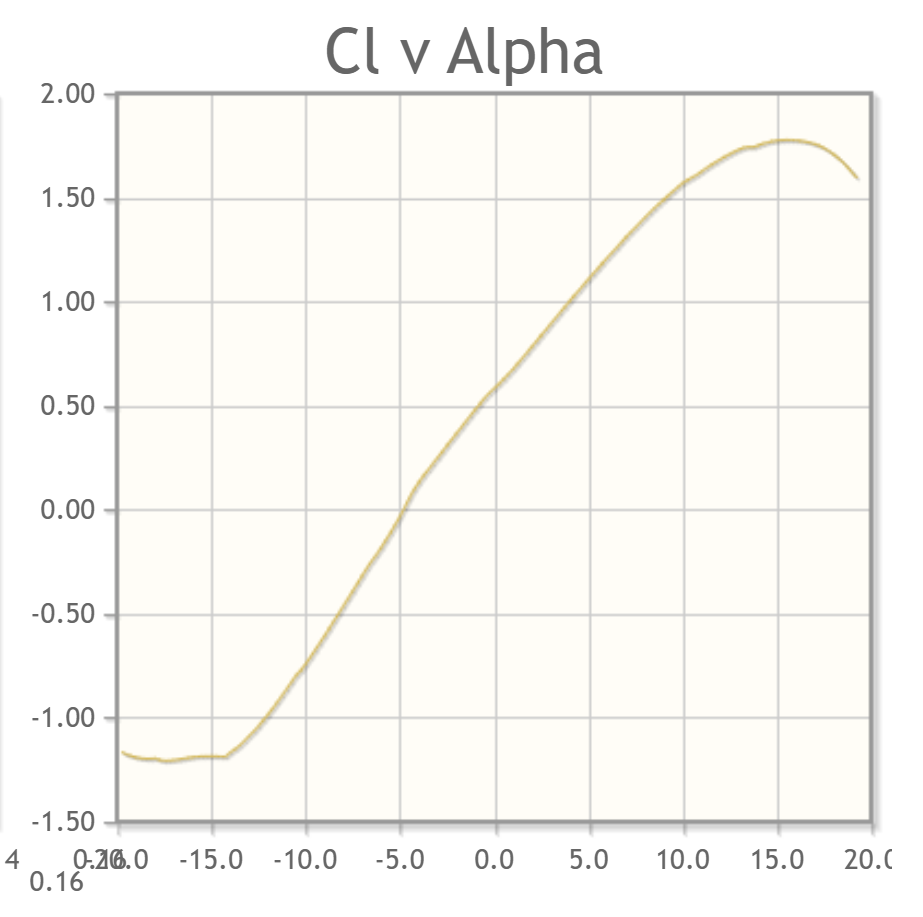

Clmin = -1.2;

Approximate 3D effects


$$C_{L_{\min } } =0\ldotp 9C_{l_{\min } } \cdot \cos \left(\Lambda_{0\ldotp 25c} \right)$$


CLmin = 0.9 .* Clmin .* cos(Sweep) 

CLmin = -0.9746


for i = 1 : length(Vspace)

    L_min = 0.5 .* rho0 .* (Vspace .^ 2) .* Sref .* Comp_Effects(CLmin, Vspace(i), Calt, Sweep);

end

n_lowerline = L_min ./ WL;

**2.4 Maximum Load Factor**

% nmax = CLmax ./ CD0

**2.5 Positive Limit Manoeuvring Load Factor**

CS 25.337 (p.217)

$n\ge 2\ldotp 5$ and $n\ge 2\ldotp 1+\left(\frac{24000}{W+10000}\right)$

nmax = 2.1 + 24000 ./ (convmass(W0 ./ g, "kg", "lbm") + 10000)

nmax = 2.1251


if nmax >= 2.5
else
    nmax = 2.5
end

nmax = 2.5000


nulti = nmax * 1.5 % Ultimate load factor

nulti = 3.7500

**2.5 Negative Limit Manoeuvring Load Factor**

nmin = -1;

**2.6 Design Manoeuvring Speed, **$V_A$

CS 25.335 (b) (p.212)


$$W_L =L=\frac{1}{2}\rho_0 V_{\textrm{S1}}^2 S_{\textrm{ref}}$$


VS1 = sqrt(2 .* WL ./ (Sref .* rho0 .* CLmax))          % Stalling speed with wing-flaps retracted at MLW (m/s)

VS1 = 88.5050

VS1_TO = sqrt(2 .* W0 ./ (Sref .* rho0 .* CLmax))       % Stalling speed with wing-flaps retracted at MTOW (m/s)

VS1_TO = 93.2924

VS1_min = sqrt(2 .* WL ./ (Sref .* rho0 .* abs(CLmin))) % Stalling speed with wing-flaps retracted at MLW (m/s)

VS1_min = 107.6305

VS0 = sqrt(2 .* WL ./ (Sref .* rho0 .* CLmaxL))         % Stalling speed in the landing configuration at MLW (m/s)

VS0 = 62.6826


$$V_A \ge V_{\textrm{S1}} \sqrt{n_{\max } }$$


VA = VS1 * sqrt(nmax)

VA = 139.9386

**2.6 Design Wing-flap Speed, **$V_F$

CS 25.335 (e) (p.214)

$V_F$ may not be less than 

(i) $1\ldotp 6V_{\textrm{S1}}$ with the wing-flaps in take-off position at maximum take-off weight

(ii) $1\ldotp 8V_{\textrm{S1}}$ with the wing-flaps in approach position at maximum landing weight

(iii) $1\ldotp 8V_{\textrm{S0}}$ with the wing-flaps in landing position at maximum landing weight

VF = 1.6 * VS1_TO

VF = 149.2679

**2.8 Plot Manoeuver envelope**

CS 25.333 (b) (p.211)

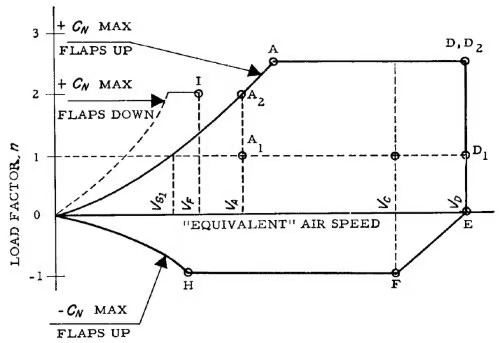

Find intersection point

% First segment of upper curve

Vspace1 = linspace(0, VS1, 1000);

L1 = 0.5 .* rho0 .* (Vspace1 .^ 2) .* Sref .* CLmax;

n_upper1 = L1 ./ WC;

% Second segment of upper curve

Vspace2 = linspace(VS1, VD, 1000);

L2 = 0.5 .* rho0 .* (Vspace2 .^ 2) .* Sref .* CLmax;

n_upper2 = L2 ./ WC;

for i = 1 : length(n_upper2)
    if n_upper2(i) <= nmax
    else
        n_upper2(i) = nmax;
    end
end

% Thrid segment of upper curve

Vspace2 = [Vspace2 VD];

n_upper2 = [n_upper2 0];

% first segment of lower curve

% I am not sure which V_s should be used here, see slide page 21

Vspace3 = linspace(0, VS1, 1000);

L1_min = 0.5 .* rho0 .* Vspace3 .^ 2 .* Sref .* CLmin;

n_lower1 = L1_min ./ WC;

% second segment of lower curve

Vspace4 = linspace(VS1, VC, 1000);

L2_min = 0.5 .* rho0 .* Vspace4 .^ 2 .* Sref .* CLmin;

n_lower2 = L2_min ./ WC;

for i = 1 : length(n_lower2)
    if n_lower2(i) >= nmin
    else
        n_lower2(i) = nmin;
    end
end

% thrid segment of lower curve

Vspace5 = linspace(VC, VD, 1000);

n_lower3 = (1 ./ (VD - VC)) .* Vspace5 + (VD ./ (VC - VD));

% First segment of upper curve with landing configuration

% I am not sure what n should be used here, see graph above

# **Plotting Gust**

## Using the book(lecture notes) (Mainini said we should not use it)

dCLdalpha = 4.4359;
cbar = 9.9496;
mu = 2*(WC/Sref)/(rhoC*g*cbar*dCLdalpha);
K = 0.88*mu/(5.3 + mu);
Ude = [20,15.2,7.6]

Ude =    20.0000   15.2000    7.6000


U = K * Ude

U =    16.3411   12.4192    6.2096


### Using CS25

CS 25.341 (a) (p.219)

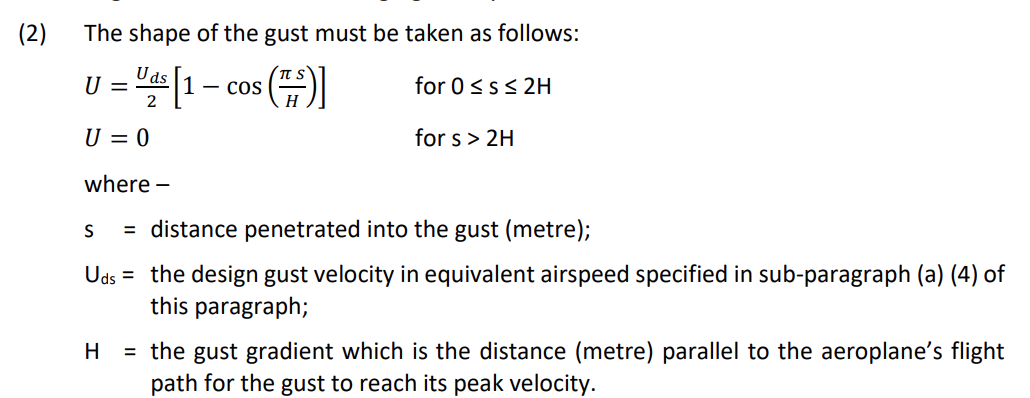

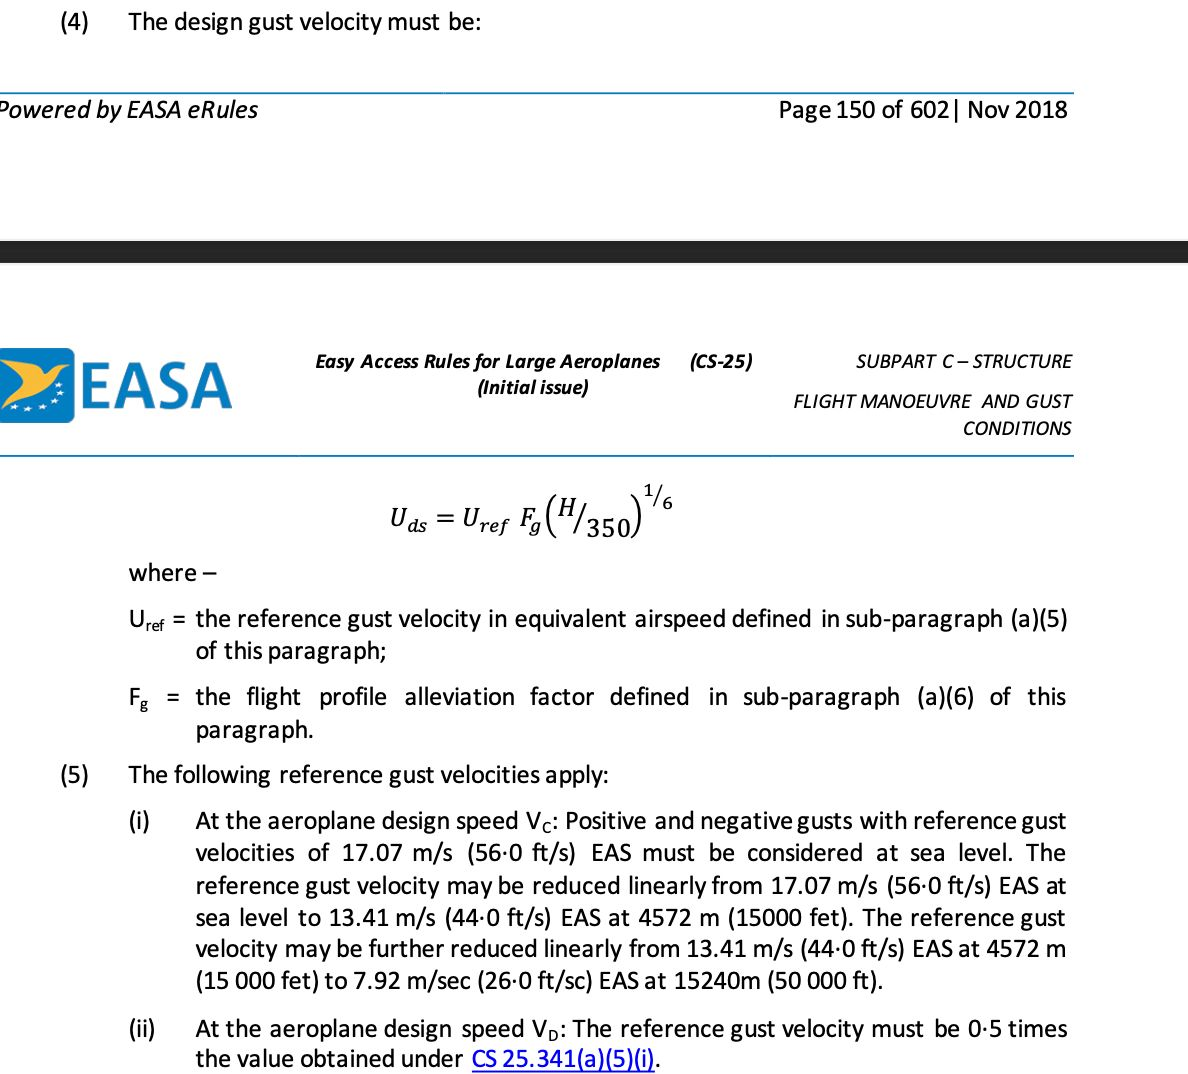

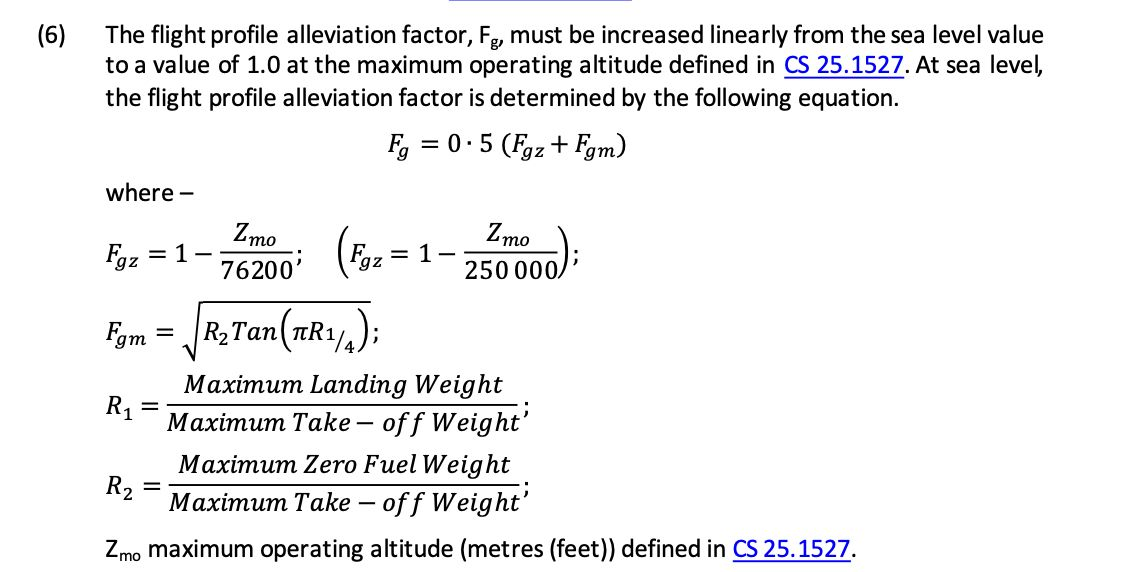

Basically, n is a function of Uds(amplitude of gust), and Uds is a function of H and Uref. H and Uref are varied according to (3) and (5) like this:

%vary H and Uref
Uref = [17.07; 13.41; 7.92]

Uref =    17.0700
   13.4100
    7.9200


Alt = [0; 4572; 15240]

Alt =            0
        4572
       15240


H = linspace(9,107,3);

Then Fg can be computed using (6). Note that it is interpolated at the cruise altitude.

Zmo = convlength(45000,'ft','m'); % in m, as given in design requirement
WML = 3795587.1; %maximum landing weight in N
WF = 1928646; %fuel weight in N
Fgz = 1 - Zmo/76200;
R1 = WML/W0;
R2 = (W0-WF)/W0;
Fgm = sqrt(R2*tan(pi*R1/4));
Fg0 = 0.5*(Fgz + Fgm)

Fg0 = 0.7504

%Fg varies linearly from sealevel to maximum altitude
%In V-n diagram, Fg at cruise altitude should be used
Fgc = (1-Fg0)/Zmo * Calt + Fg0;

## **Using old CS25:**

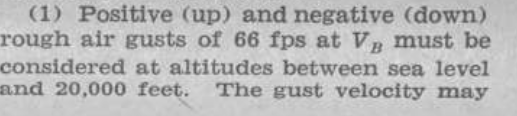

our cruise altitude is 28000 ft

Uds due to VB = 58.53 fps

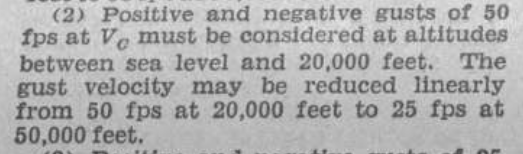

Uds due to VC = 43.33fps

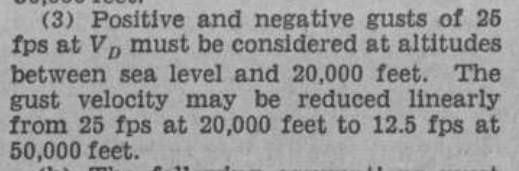

Uds due to VD = 21.67fps

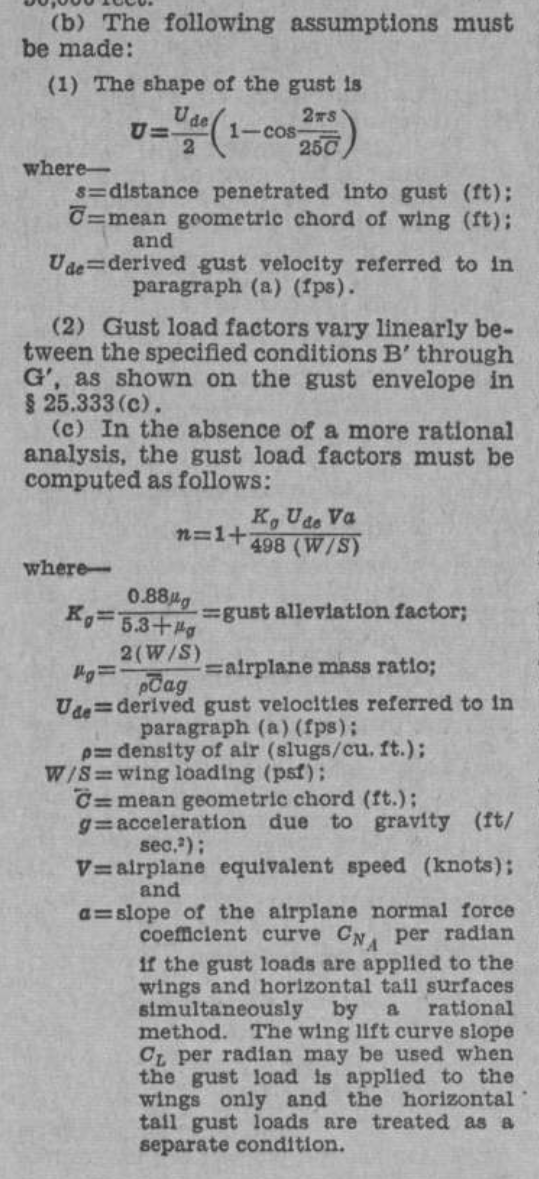

mug = 2*(WC/Sref*0.020885)/(rhoC*0.00194032*cbar*3.28084*dCLdalpha*32.1740485564)

mug = 68.7927

Kg = 0.88*mug/(5.3 + mug)

Kg = 0.8171

Uds_old = [58.53,43.33,21.67];

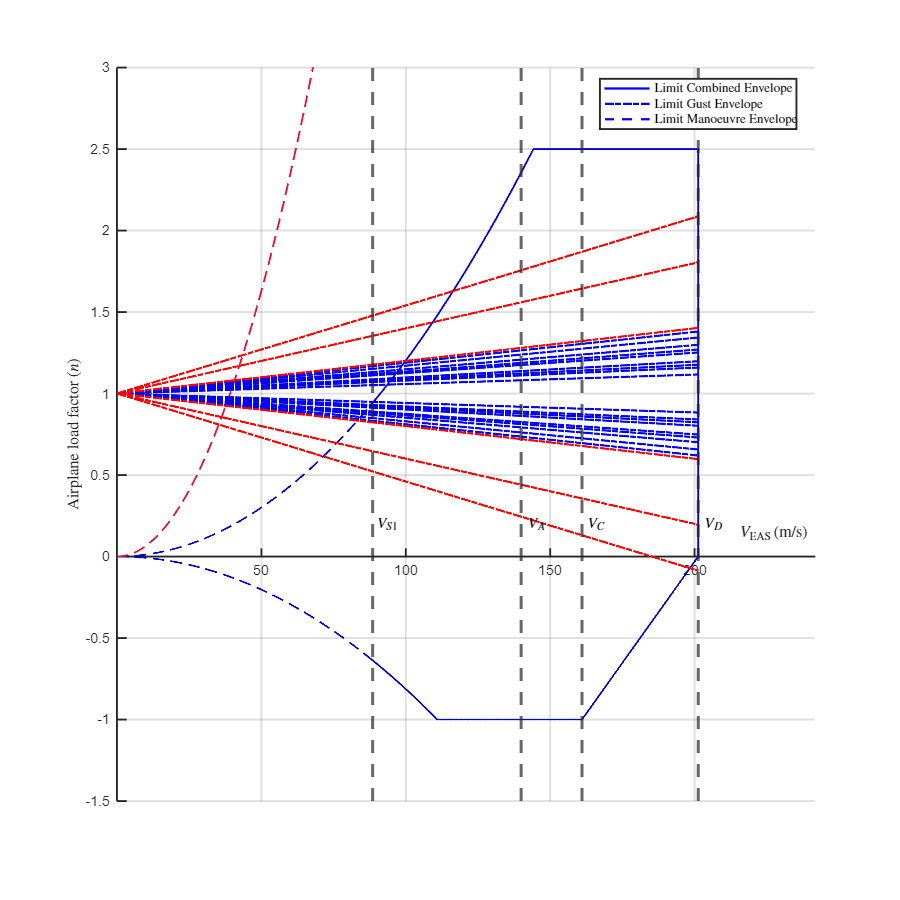

figure(1)
clf;

% Plotting various lines
plot(Vspace1, n_upper1, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25);
hold on;
plot(Vspace2, n_upper2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25);
plot(Vspace3, n_lower1, '--', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25);
plot(Vspace4, n_lower2, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25);
plot(Vspace5, n_lower3, '-', 'Color', [0/255 0/255 205/255], 'LineWidth', 1.25);
plot(Vspace, n_upperline_L, '--', 'Color', [220/255 20/255 60/255], 'LineWidth', 1.25);
labels = ["VB", "VC", "VD"];

% Adding gust load factor lines
for i = 1:size(Uref,1)
    for j = 1:size(H,2)
    % Compute gust load factors
        Uds = Uref(i).*Fgc.*(H(j)./350).^(1/6);
        ngust_1 = 1 + rhoC * Uds .* Vspace .* dCLdalpha / (2 * WC / Sref);
        ngust_2 = 1 - rhoC * Uds .* Vspace .* dCLdalpha / (2 * WC / Sref);
        
        % Plot gust lines
        plot(Vspace, ngust_1, 'b-.', 'LineWidth', 1.5);
        hold on;
        plot(Vspace, ngust_2, 'b-.', 'LineWidth', 1.5);
        hold on;
    
        % Add labels at the end of each line with LaTeX font
        % text(Vspace(end)+5, ngust_1(end), ['$' char(labels(i)) '$'], ...
        %     'Interpreter', 'latex', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'FontSize', 10);
        % text(Vspace(end)+5, ngust_2(end), ['-$' char(labels(i)) '$'], ...
        %     'Interpreter', 'latex', 'HorizontalAlignment', 'left', 'VerticalAlignment', 'middle', 'FontSize', 10);
    end
end

for i = 1:length(Uds_old)
    Vspacekts = Vspace.*1.94384;
    ngust_1_old = 1 + Kg*Uds_old(i).*Vspacekts.*dCLdalpha/(498*WC/Sref*0.020885);
    ngust_2_old = 1 - Kg*Uds_old(i).*Vspacekts.*dCLdalpha/(498*WC/Sref*0.020885);

    plot(Vspace, ngust_1_old, 'r-.', 'LineWidth', 1.5);
    hold on;
    plot(Vspace, ngust_2_old, 'r-.', 'LineWidth', 1.5);
    hold on;

end



% Vertical lines
xline(VD, '--', 'LineWidth', 2);
xline(VC, '--', 'LineWidth', 2);
xline(VA, '--', 'LineWidth', 2);
xline(VS1, '--', 'LineWidth', 2);

% Adding labels to vertical lines with LaTeX font
text(VD+5, 0.2, '$V_D$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center');
text(VC+5, 0.2, '$V_C$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center');
text(VA+5, 0.2, '$V_A$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center');
text(VS1+5, 0.2, '$V_{S1}$', 'Interpreter', 'latex', 'HorizontalAlignment', 'center');

% Axis labels with LaTeX font
xlabel('$V_{\mathrm{EAS}} \, (\mathrm{m/s})$', 'Interpreter', 'latex');
ylabel('Airplane load factor $(n)$', 'Interpreter', 'latex');

% Customize axis appearance
set(gca, 'FontSize', 9.5); % Set axis font size
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';
ax.LineWidth = 1.25;
ax.Box = 'off';

% Set plot limits and grid
xlim([0 VD * 1.2]);
ylim([-1.5 3]);
grid on;
% Desired plots for the legend
x = 1:10;
h1 = plot(-x, rand(1, 10), 'b-', 'LineWidth', 1.5); % Solid line
h2 = plot(-x, rand(1, 10), 'b-.', 'LineWidth', 1.5); % Dash-dot line
h3 = plot(-x, rand(1, 10), 'b--', 'LineWidth', 1.5); % Dashed line

% Add legend for the selected plots
legend([h1, h2, h3], {'Limit Combined Envelope', 'Limit Gust Envelope', 'Limit Manoeuvre Envelope'}, ...
    'Location', 'best', 'Interpreter', 'latex');

% Set figure size
set(gcf, 'Position', [0 0 1000 1000]);